# Module 2: Action Functional Gradient Descent (AFGD) algorithm

clear all
close all

## Load model

lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)
plotnam = "2-Schlogl"

model_name = "Selkov"

model_name = "Selkov"

plotnam = "Selkov"

plotnam = "Selkov"

model_name = "SYN3_FINAL"
plotnam = "12-D Syntrophy model"

model_name = "Cluster_3_catalyst"
plotnam = "3-D Cluster model with catalysis"

model_name = "Cluster_3_catalyst_w_temp"
plotnam = "3-D Cluster model with catalysis & templating"

#### Load ..._Ham.mat from 'data' folder

load('..\Data\'+model_name+'_Ham.mat')

#### Load heteroclinic network

i = row in hc_net. j = column in hc_net - 1 

load('..\Data\' + model_name + '_hcnet.mat')
pos_root_arr
hc_net
i = 1; j = 1;
sad_pt = i; stab_pt_choice = j;

i = 1; j = 2;
sad_pt = i; stab_pt_choice = j;


#### Load initial condition

Straight 

load('..\Data\' + model_name + '_initcond_'+string(i)...
        +'_'+string(j)+'straight.mat')

Spiral

load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat')
traj_ic = double(traj_ic);

figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')

#### Sample space uniform and plot

%Space uniform sampling
traj_pts = 2500;
traj_ic = double(traj_ic);
[traj,len_curve_prime] = space_uniform_sampling(traj_ic,traj_pts);
%Plot
figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')
hold on
plot(traj(:,1),traj(:,2:end),'.-')
hold off
legend('traj-ic','Uniform space')
title(plotnam + ' IC')

#### Load from existing data

save('traj_n_s_2000_Schlogl.mat',"traj_n_s")

load( "..\Data\Selkov_descend_1_2spiral_2500_09-Aug-2022.mat")
%Space uniform sampling
traj_pts = 4000;
traj_ic = PS_traj(:,1:num_spec);
[traj,len_curve_prime] = space_uniform_sampling(traj_ic,traj_pts);


load('traj_n_s_2000_Schlogl.mat')
traj = traj_n_s; traj_pts = size(traj,1);
[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);

load("..\Data\Schlogl_1_2_descend_1_2straight_500_11-Jul-2022.mat")
%savenam = "..\Data\Schlogl_1_2_descend_1_2straight_500_11-Jul-2022.mat"

iter = size(S_arr,1);
traj_pts_new = 2000;
iter = 80;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
traj = PS_traj(:,1:num_spec);
%traj = time_uniform_filter(PS_traj(:,1:num_spec),t_traj,2000,40);
[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts_new);

load('..\Data\Selkov_4000_anneal_traj.mat')
[traj,len_curve_prime] = space_uniform_sampling(traj,size(traj,1));

## Initialize Descender

%number of points in trajectory
traj_pts = size(traj,1)

traj_pts =         4000



%Initialize arrays for saving and delta_x_s
Initialize_descender

S_arr =    0.446521297423587



%Save data to file in the data folder
%savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
%+'_'+string(stab_pt_choice)+'straight_'+string(traj_pts)+'_'+string(date)+'.mat'
%Save data to file in the data folder (for spiral)
savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'spiral_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "..\Data\Selkov_descend_1_2spiral_4000_11-Aug-2022.mat"

%Save plots 
%folder_nam = 'Schlogl_2';
folder_nam = "Selkov";
save_plot_name_root = 'Plots/'+folder_nam+'/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+string(date)

save_plot_name_root = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022"


%Plot PS_traj and save
save_plot_name = 'Plots/'+folder_nam+'/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+'_PS_traj_IC.png'

save_plot_name = "Plots/Selkov/Selkov_1_2_4000__PS_traj_IC.png"

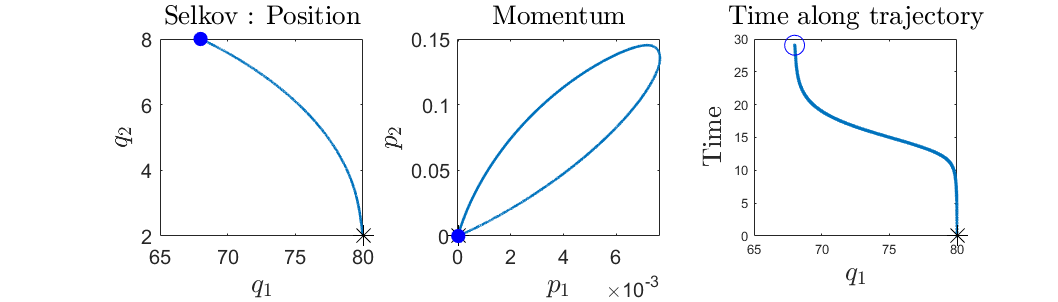

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);


%delta_x_s
delta_x_s =  smooth_traj_butter(delta_x,f0); 

%Plot delta_x and save
save_plot_name = 'Plots/'+folder_nam+'/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+'_deltax_IC.png'

save_plot_name = "Plots/Selkov/Selkov_1_2_4000__deltax_IC.png"

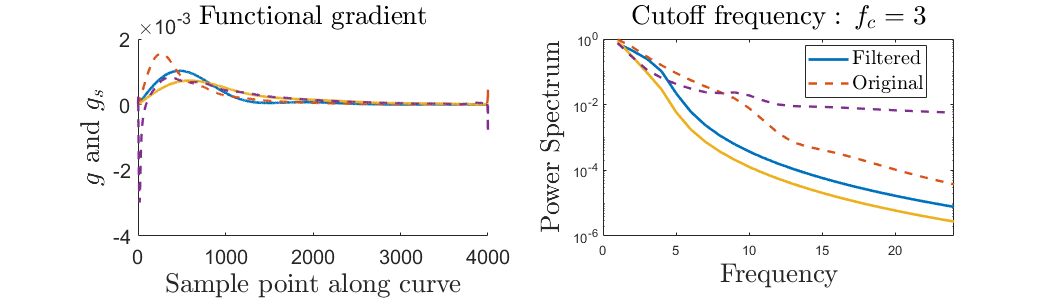

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);

## Perform the actual descent

%Actual descender
eps_ic = 1; eps = eps_ic; eps_min = 0.005;     %Initial and least step size
delta_S = 10; err_thresh = 10^(-1); 
f0_max = 40; f0_step = 0.1; f0_init = f0;
eps_S_thresh = 10^(-7); delta_S_thresh = 5*10^(-6);
iter_max = 50; iter = 1; a_min=100; a_thresh = 0.001;
delta_S_thresh_eps = 10^(-7);time_uniform_f = 45;
%time_uniform_f = 35 for Schlogl

f0 = 5; eps_ic = 0.25; eps = eps_ic; eps_min = 0.001; delta_S_thresh = 10^(-9);
delta_S_thresh_eps = 10^(-8);

iter = 30
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
traj = PS_traj(:,1:num_spec);
delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,iter);

iter_max = 80

iter_max =     80


delta_S_thresh = 5*10^(-7);

delta_S =      6.860456951973681e-06


delta_S =      8.055251765393123e-06


delta_S =      1.329147798517782e-05


delta_S =     -1.807912252627109e-06


ans =    2.000000000000000   0.125000000000000   0.446519489511335  -0.000001807912253   3.000000000000000


a_min =    1.969453207243937


delta_S =      1.519032942004506e-05


delta_S =      3.027339988581623e-06


delta_S =      1.289387220959615e-05


delta_S =      1.482717071776829e-05


delta_S =      1.299829798240282e-05


delta_S =     -1.487978368852616e-07


ans =    3.000000000000000   0.003906250000000   0.446519340713498  -0.000000148797837   3.000000000000000


a_min =    1.969455831212829


delta_S =      6.121449557527914e-06


delta_S =      6.491888207005303e-06


delta_S =      8.077316268673140e-06


delta_S =      1.513211635439937e-05


delta_S =      1.249497620026130e-05


delta_S =      1.236121227599085e-05


delta_S =      4.507939033393527e-06


delta_S =      1.628903476080801e-05


delta_S =      1.506563986503062e-05


ans =    4.000000000000000                   0   0.446519340713498                   0   3.100000000000000


a_min =    1.969492711053245


delta_S =      8.060261848963357e-06


delta_S =      1.055267092320289e-05


delta_S =      3.235511068233610e-06


delta_S =      1.696476499662980e-05


delta_S =      1.068586126812265e-05


delta_S =      1.531803620458128e-05


delta_S =      1.392750044265645e-05


delta_S =      1.335247432926456e-05


delta_S =      1.269764205324986e-05


ans =    5.000000000000000                   0   0.446519340713498                   0   3.200000000000000


a_min =    1.969530945528402


delta_S =      7.230734905161462e-06


delta_S =      1.164905945172379e-05


delta_S =      1.156019414894072e-05


delta_S =      1.457758621481453e-05


delta_S =      7.074918003557862e-06


delta_S =      1.642215524289004e-05


delta_S =      1.355937173658228e-05


delta_S =      5.786706999688640e-06


delta_S =      1.081767627447716e-05


ans =    6.000000000000000                   0   0.446519340713498                   0   3.300000000000000


a_min =    1.969589140817037


delta_S =     -5.209071597289672e-06


ans =    7.000000000000000   1.000000000000000   0.446514131641901  -0.000005209071597   3.400000000000000


a_min =    1.957219912815391


delta_S =     -6.637713636348241e-06


ans =    8.000000000000000   1.000000000000000   0.446507493928264  -0.000006637713636   3.400000000000000


a_min =    1.944817113691624


delta_S =      6.913321786705673e-06


delta_S =     -7.205933096221528e-06


ans =    9.000000000000000   0.500000000000000   0.446500287995168  -0.000007205933096   3.400000000000000


a_min =    1.938637100970408


delta_S =      1.654648080673393e-05


delta_S =      1.749800256367617e-05


delta_S =      1.518648847786963e-06


delta_S =      1.469839947809692e-06


delta_S =      8.878940699619253e-06


delta_S =      6.401642847153610e-06


delta_S =      8.787231713491828e-06


delta_S =      8.317694896731176e-07


ans =   10.000000000000000                   0   0.446500287995168                   0   3.400000000000000


a_min =    1.938682581556023


save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_deltax_10.png"

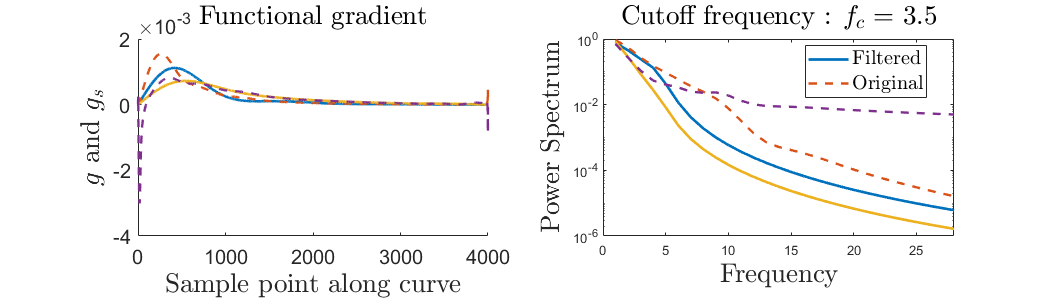

save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_PS_traj_10.png"

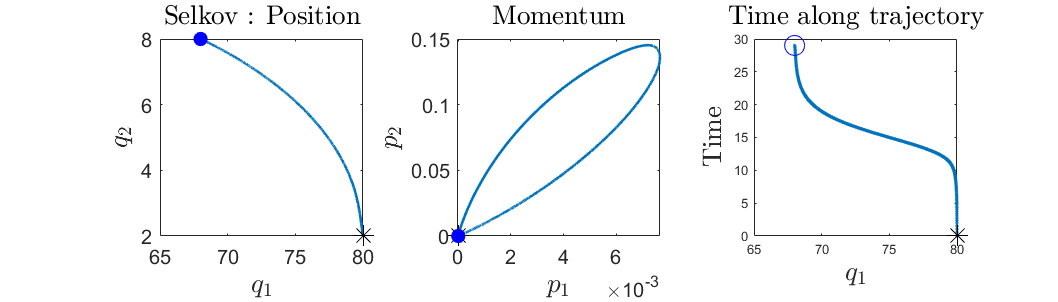

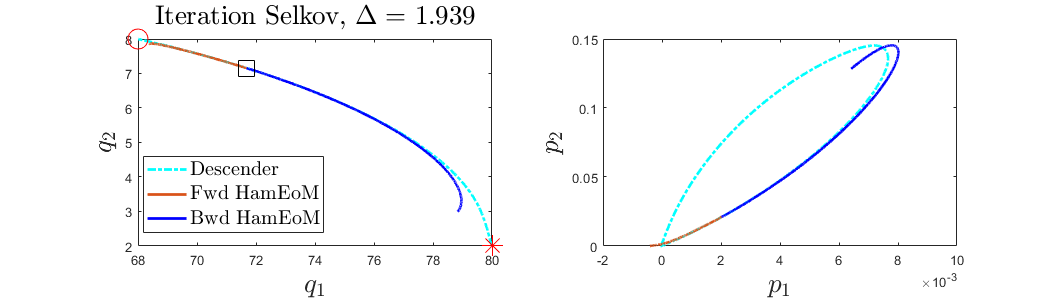

a =    1.938682581556023


delta_S =      1.178830487785776e-05


delta_S =      1.311084393723627e-05


delta_S =      7.998274366705083e-07


delta_S =      1.757824071302316e-05


delta_S =      1.009545210817198e-05


delta_S =      3.215768774322836e-06


delta_S =      3.333709527097994e-06


delta_S =      1.318914355297185e-05


delta_S =      4.939149433946799e-06


ans =   11.000000000000000                   0   0.446500287995168                   0   3.500000000000000


a_min =    1.938714818612997


delta_S =      3.442087176785957e-06


delta_S =      1.268296508488698e-05


delta_S =      1.590348127983310e-05


delta_S =      3.056422276603854e-06


delta_S =      1.953725404579831e-05


delta_S =      2.043653321071037e-06


delta_S =      8.553719552939487e-06


delta_S =      1.959208414581415e-05


delta_S =      7.015500874618663e-06


ans =   12.000000000000000                   0   0.446500287995168                   0   3.600000000000001


a_min =    1.938770829573463


delta_S =     -9.803711593536768e-06


ans =   13.000000000000000   1.000000000000000   0.446490484283574  -0.000009803711594   3.700000000000001


a_min =    1.926313652186884


delta_S =      1.430191960904992e-05


delta_S =      4.544793437866179e-06


delta_S =      7.553760385692332e-06


delta_S =      9.470957511747979e-06


delta_S =      5.844697336110372e-06


delta_S =      9.334637569746729e-06


delta_S =      6.913665964058957e-06


delta_S =      1.409520199224801e-06


delta_S =      3.663167443268556e-06


ans =   14.000000000000000                   0   0.446490484283574                   0   3.700000000000001


a_min =    1.926357845688982


delta_S =      1.028804969277486e-05


delta_S =      1.485718141824854e-05


delta_S =      1.660467800035370e-06


delta_S =      3.956652497805191e-06


delta_S =      5.103664335148750e-06


delta_S =      3.828698768082450e-06


delta_S =      4.252077505872975e-06


delta_S =      1.013998110388492e-05


delta_S =      1.311262591102702e-05


ans =   15.000000000000000                   0   0.446490484283574                   0   3.800000000000001


a_min =    1.926388663295670


delta_S =      8.861815614658042e-06


delta_S =      4.056033429067352e-06


delta_S =      5.658841399358572e-06


delta_S =      2.370409215024516e-06


delta_S =      3.009684653554334e-06


delta_S =      9.007265375893247e-06


delta_S =      2.987595812686816e-06


delta_S =      8.935367661777605e-06


delta_S =      4.386177336113128e-06


ans =   16.000000000000000                   0   0.446490484283574                   0   3.900000000000001


a_min =    1.926463925935736


delta_S =     -2.729602923801089e-06


ans =   17.000000000000000   1.000000000000000   0.446487754680651  -0.000002729602924   4.000000000000001


a_min =    1.914251705683005


delta_S =     -7.559316187344400e-06


ans =   18.000000000000000   1.000000000000000   0.446480195364463  -0.000007559316187   4.000000000000001


a_min =    1.902139289690854


delta_S =     -4.598861001015031e-06


ans =   19.000000000000000   1.000000000000000   0.446475596503462  -0.000004598861001   4.000000000000001


a_min =    1.890102328517921


delta_S =      2.572990619065241e-06


delta_S =     -2.531099352054422e-06


ans =   20.000000000000000   0.500000000000000   0.446473065404110  -0.000002531099352   4.000000000000001


a_min =    1.884130676612310


save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_deltax_20.png"

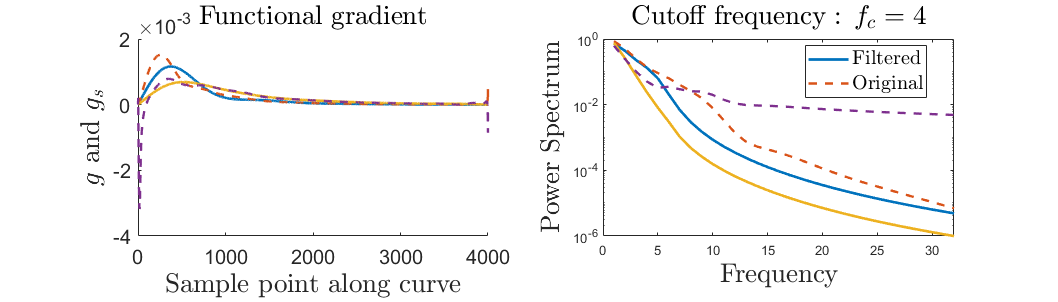

save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_PS_traj_20.png"

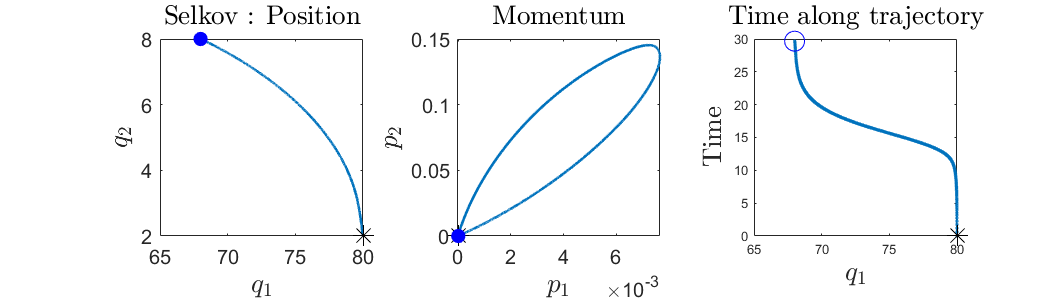

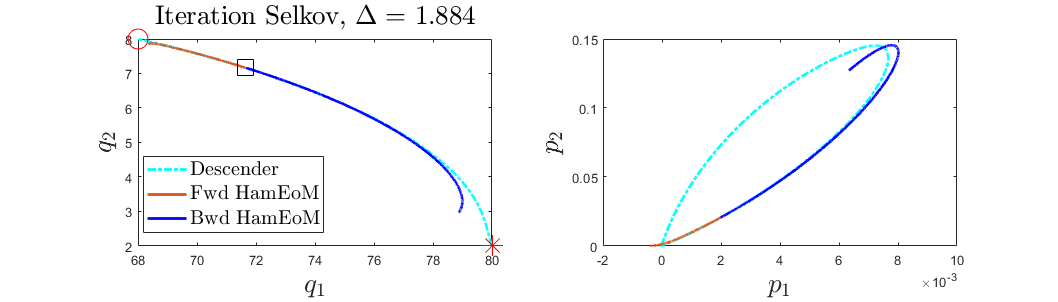

a =    1.884130676612310


delta_S =      2.806833608315351e-07


delta_S =     -3.618361883173105e-06


ans =   21.000000000000000   0.250000000000000   0.446469447042227  -0.000003618361883   4.000000000000001


a_min =    1.881156099817722


delta_S =      3.426250596849645e-06


delta_S =      3.113345800331846e-06


delta_S =      3.065209685348957e-06


delta_S =      5.306825596185227e-06


delta_S =      2.654413782832155e-06


delta_S =      2.733885817007842e-06


delta_S =      1.283077133429344e-08


ans =   22.000000000000000                   0   0.446469447042227                   0   4.000000000000001


a_min =    1.881209025970676


delta_S =      3.231104612144708e-06


delta_S =      7.458500625834308e-06


delta_S =      4.697266360320640e-06


delta_S =      4.447427185250152e-06


delta_S =      3.368451420460161e-06


delta_S =      5.371445266744157e-06


delta_S =      3.916479741239431e-06


delta_S =      2.999912335432953e-06


delta_S =      1.670159669842075e-06


ans =   23.000000000000000                   0   0.446469447042227                   0   4.100000000000001


a_min =    1.881235984655334


delta_S =      5.770042367236883e-07


delta_S =      7.800274859914857e-07


delta_S =      3.866518598460988e-06


delta_S =      9.277251168948730e-07


delta_S =      3.864711167200774e-07


delta_S =      7.558508492933047e-06


delta_S =      5.685004351552170e-06


delta_S =      8.929192344409032e-07


delta_S =      1.636486000988757e-06


ans =   24.000000000000000                   0   0.446469447042227                   0   4.200000000000000


a_min =    1.881302438278752


delta_S =      6.245559623918595e-07


delta_S =     -1.992135567285835e-06


ans =   25.000000000000000   0.500000000000000   0.446467454906660  -0.000001992135567   4.300000000000000


a_min =    1.875291804945905


delta_S =     -1.729876243194983e-06


ans =   26.000000000000000   0.500000000000000   0.446465725030417  -0.000001729876243   4.300000000000000


a_min =    1.869289836381761


delta_S =     -2.819727712766174e-06


ans =   27.000000000000000   0.500000000000000   0.446462905302704  -0.000002819727713   4.300000000000000


a_min =    1.863300425236845


delta_S =     -4.652961099915753e-06


ans =   28.000000000000000   0.500000000000000   0.446458252341604  -0.000004652961100   4.300000000000000


a_min =    1.857325665548672


delta_S =      1.208235678229475e-06


delta_S =      5.157334810712566e-06


delta_S =      4.968543770800249e-06


delta_S =      4.606304089660451e-06


delta_S =      3.096691600035228e-06


delta_S =      2.900886936163527e-06


delta_S =      2.459871506876876e-06


delta_S =      2.365798189574164e-06


ans =   29.000000000000000                   0   0.446458252341604                   0   4.300000000000000


a_min =    1.857372849027120


delta_S =      1.723469603365224e-06


delta_S =      1.414819218281682e-06


delta_S =      8.364370698898949e-06


delta_S =      4.889993536538739e-06


delta_S =      2.068068342631069e-06


delta_S =      4.687953913451448e-06


delta_S =      3.342231382652550e-06


delta_S =      2.653700779675638e-06


delta_S =      3.073310569978727e-06


ans =   30.000000000000000                   0   0.446458252341604                   0   4.399999999999999


a_min =    1.857393209283821


save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_deltax_30.png"

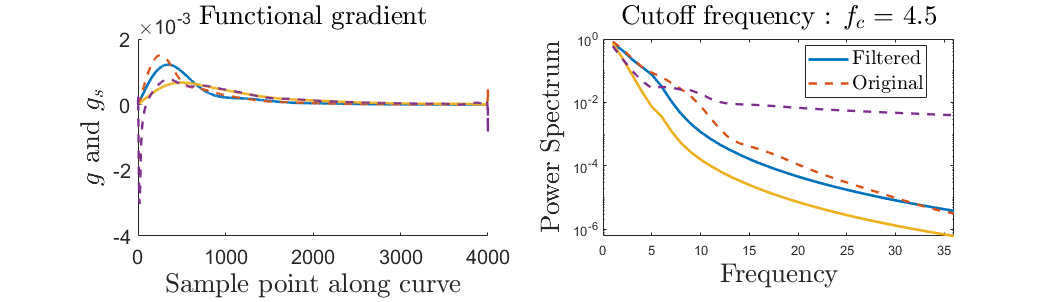

save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_PS_traj_30.png"

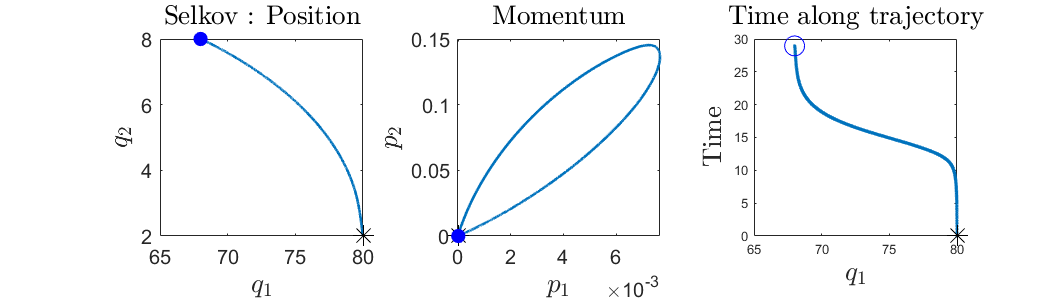

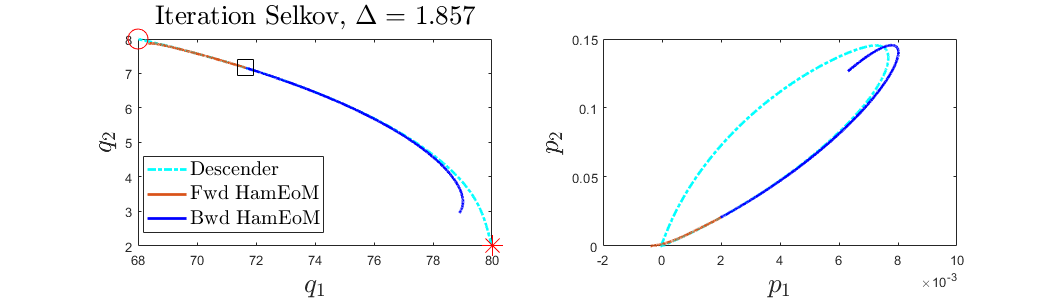

a =    1.857393209283821


delta_S =      2.411841571514639e-06


delta_S =      4.395085663022602e-06


delta_S =      4.572058429075376e-06


delta_S =      1.512361209154989e-06


delta_S =      2.329979090553991e-06


delta_S =      1.619319727808044e-06


delta_S =      5.542899452981587e-06


delta_S =      1.029417661002618e-06


delta_S =      5.076312336260713e-06


ans =   31.000000000000000                   0   0.446458252341604                   0   4.499999999999999


a_min =    1.857432937684561


delta_S =      2.553519656500747e-06


delta_S =      5.230220507412842e-06


delta_S =      7.767494256794016e-06


delta_S =      6.860594035484890e-06


delta_S =      4.804597328267324e-06


delta_S =      6.533176737266722e-06


delta_S =      9.374435276487958e-06


delta_S =      9.303687725337184e-06


delta_S =      5.841851969334844e-06


ans =   32.000000000000000                   0   0.446458252341604                   0   4.599999999999999


a_min =    1.857518120012677


delta_S =      1.897358114399950e-06


delta_S =      7.900651649017654e-06


delta_S =      5.598022686847948e-06


delta_S =      2.317844177091022e-06


delta_S =      6.659393166574823e-06


delta_S =      9.138930465946160e-06


delta_S =      7.448907679008521e-06


delta_S =      7.534709635048653e-06


delta_S =      1.007399456509628e-05


ans =   33.000000000000000                   0   0.446458252341604                   0   4.699999999999998


a_min =    1.857561213685102


delta_S =      1.387719117729169e-06


delta_S =      5.000333972715598e-06


delta_S =      4.005529546657893e-06


delta_S =      1.345203056057898e-06


delta_S =      5.259223317732875e-06


delta_S =      4.300207445240289e-06


delta_S =      3.501936215677404e-06


delta_S =      5.818975181814956e-06


delta_S =      7.329963870483791e-06


ans =   34.000000000000000                   0   0.446458252341604                   0   4.799999999999998


a_min =    1.857601787480943


delta_S =      5.060954366198356e-06


delta_S =      4.555139418382925e-06


delta_S =      6.986092811689382e-06


delta_S =      6.411169787556847e-06


delta_S =      6.132511778167427e-06


delta_S =      5.972211460980592e-06


delta_S =      9.218251920350973e-06


delta_S =      5.955561899029238e-06


delta_S =      5.832372103387051e-06


ans =   35.000000000000000                   0   0.446458252341604                   0   4.899999999999998


a_min =    1.857652764791134


delta_S =      1.437978964902165e-06


delta_S =      7.297199849598535e-06


delta_S =      9.470192419980261e-06


delta_S =      7.602882561630331e-06


delta_S =      6.768974866955269e-06


delta_S =      1.011432165864967e-05


delta_S =      7.107759429580973e-06


delta_S =      3.927481220411533e-06


delta_S =      4.610740406196800e-06


ans =   36.000000000000000                   0   0.446458252341604                   0   4.999999999999997


a_min =    1.857714313981281


delta_S =      8.236819080686963e-07


delta_S =      5.483905672676315e-06


delta_S =      6.390078799656251e-06


delta_S =      6.534582733586092e-06


delta_S =      9.532436873738170e-06


delta_S =      7.537871192120349e-06


delta_S =      7.136455250855711e-06


delta_S =      5.389106850883785e-06


delta_S =      4.995321083611781e-06


ans =   37.000000000000000                   0   0.446458252341604                   0   5.099999999999997


a_min =    1.857750285995074


delta_S =     -3.820159486966901e-06


ans =   38.000000000000000   1.000000000000000   0.446454432182117  -0.000003820159487   5.199999999999997


a_min =    1.845311740635719


delta_S =     -1.047213954236126e-05


ans =   39.000000000000000   1.000000000000000   0.446443960042575  -0.000010472139542   5.199999999999997


a_min =    1.833148705180482


delta_S =     -7.809737461728083e-07


ans =   40.000000000000000   1.000000000000000   0.446443179068828  -0.000000780973746   5.199999999999997


a_min =    1.821207589784073


save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_deltax_40.png"

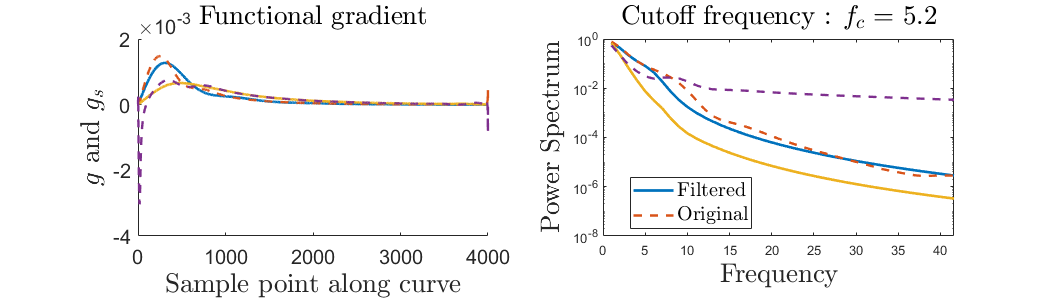

save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_PS_traj_40.png"

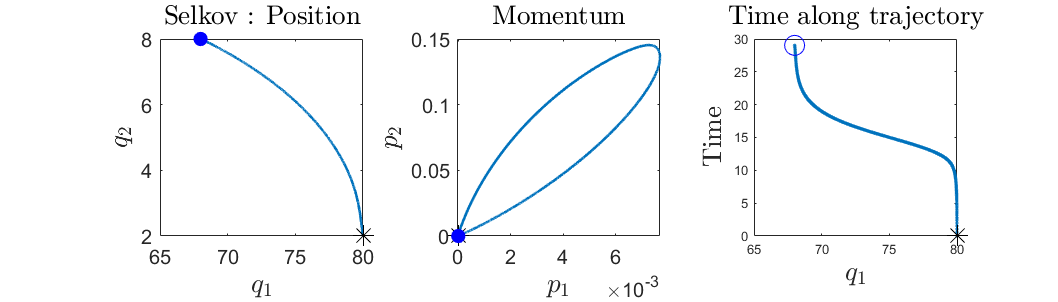

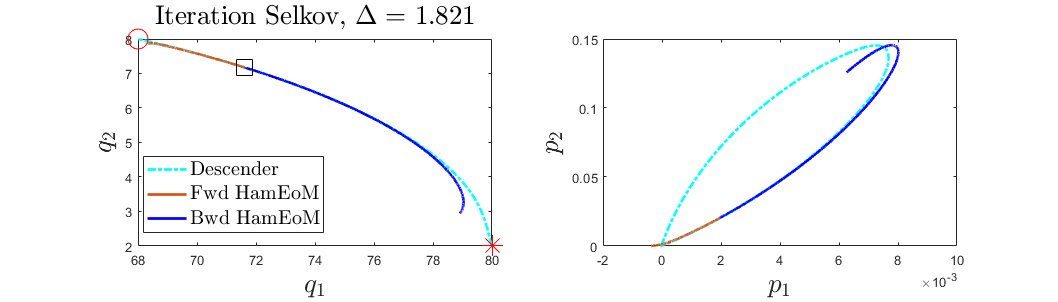

a =    1.821207589784073


delta_S =      4.261025861151957e-06


delta_S =      6.217319921841824e-06


delta_S =     -4.955558234820412e-06


ans =   41.000000000000000   0.250000000000000   0.446438223510594  -0.000004955558235   5.199999999999997


a_min =    1.818272763341704


delta_S =      1.410672204893437e-05


delta_S =      8.734508820718023e-06


delta_S =      1.789717868183605e-06


delta_S =     -5.627382670403414e-07


ans =   42.000000000000000   0.031250000000000   0.446437660772327  -0.000000562738267   5.199999999999997


a_min =    1.817907245310127


delta_S =      2.410114084416826e-06


delta_S =      3.971771922739453e-06


delta_S =      1.967330001018119e-06


delta_S =      1.608969089517132e-06


ans =   43.000000000000000                   0   0.446437660772327                   0   5.199999999999997


a_min =    1.817969441464262


delta_S =     -1.497044065046360e-06


ans =   44.000000000000000   1.000000000000000   0.446436163728262  -0.000001497044065   5.299999999999996


a_min =    1.806222451834595


delta_S =      3.712528738986087e-06


delta_S =     -2.140730178845640e-06


ans =   45.000000000000000   0.500000000000000   0.446434022998083  -0.000002140730179   5.299999999999996


a_min =    1.800413523793136


delta_S =      7.908241844156727e-06


delta_S =     -5.075882430760625e-06


ans =   46.000000000000000   0.250000000000000   0.446428947115652  -0.000005075882431   5.299999999999996


a_min =    1.797526967734540


delta_S =      1.455983589243592e-05


delta_S =      1.534592074636798e-05


delta_S =      3.134629616041718e-06


delta_S =      2.166570048478533e-06


delta_S =      1.902630810679540e-06


delta_S =      1.785961543654402e-06


delta_S =      1.661531011659667e-05


ans =   47.000000000000000                   0   0.446428947115652                   0   5.299999999999996


a_min =    1.797561997405070


delta_S =      1.029162674870410e-05


delta_S =      1.514105609556893e-05


delta_S =      1.457510150881802e-05


delta_S =      1.639318214452512e-05


delta_S =      1.647240413565898e-05


delta_S =      1.250152448190045e-05


delta_S =      1.637170446006087e-05


delta_S =      1.568187590028636e-05


delta_S =      1.494606293217515e-05


ans =   48.000000000000000                   0   0.446428947115652                   0   5.399999999999996


a_min =    1.797629406574094


delta_S =      1.163131610149026e-05


delta_S =      1.163015111954602e-05


delta_S =      1.641927850593028e-05


delta_S =      1.616699996848103e-05


delta_S =      1.460248695800415e-05


delta_S =      1.822233256576489e-05


delta_S =      1.662625197579315e-05


delta_S =      1.561695807411612e-05


delta_S =      1.334848313400139e-05


ans =   49.000000000000000                   0   0.446428947115652                   0   5.499999999999996


a_min =    1.797661289118179


delta_S =      7.552932178966909e-06


delta_S =      1.100593264596883e-05


delta_S =      1.323837883615564e-05


delta_S =      1.549316273030676e-05


delta_S =      1.736733025980985e-05


delta_S =      1.647785348229958e-05


delta_S =      1.647804805221531e-05


delta_S =      1.654319760668876e-05


delta_S =      1.606442833873567e-05


ans =   50.000000000000000                   0   0.446428947115652                   0   5.599999999999995


a_min =    1.797706937820324


save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_deltax_50.png"

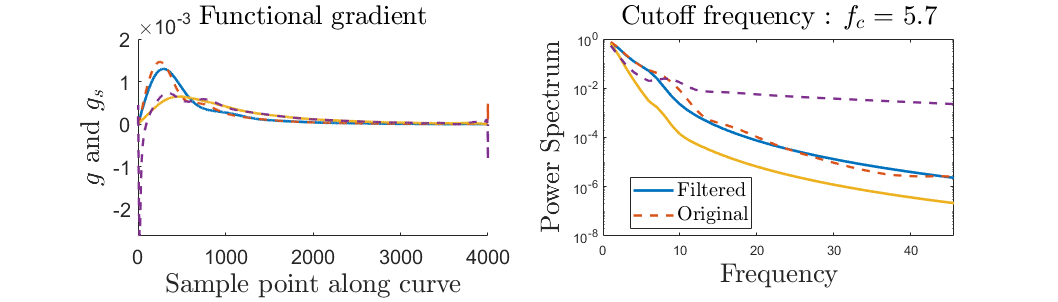

save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_PS_traj_50.png"

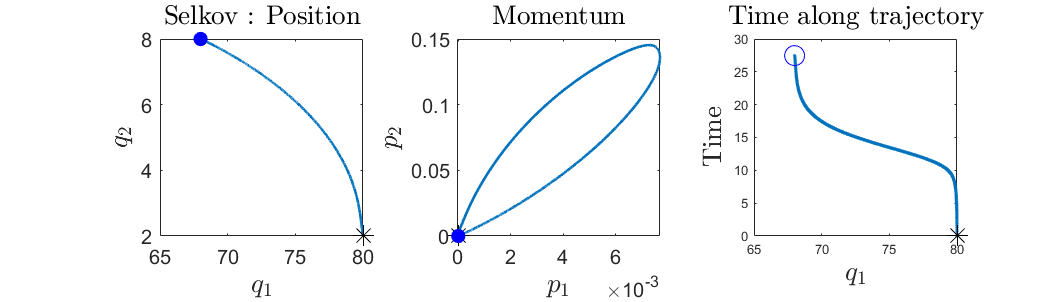

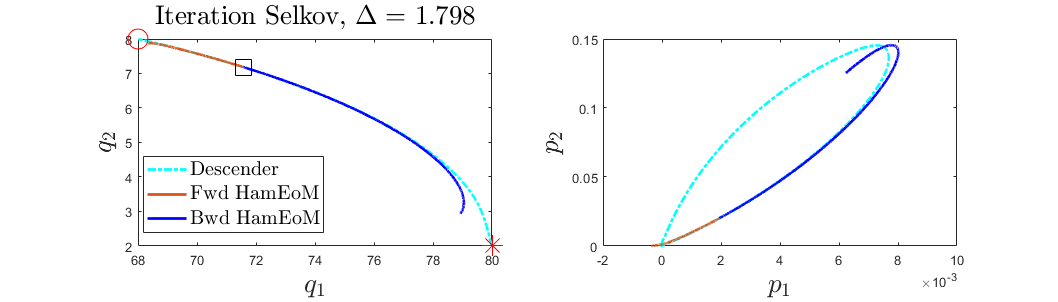

a =    1.797706937820324


delta_S =      7.831659283474846e-06


delta_S =      9.756993224419030e-06


delta_S =      1.194724401598624e-05


delta_S =      1.449706472211876e-05


delta_S =      1.620080323688766e-05


delta_S =      1.417117697449788e-05


delta_S =      1.211312828514055e-05


delta_S =      1.825515129938449e-05


delta_S =      1.472264375912413e-05


ans =   51.000000000000000                   0   0.446428947115652                   0   5.699999999999995


a_min =    1.797760147752403


delta_S =      1.010162075387733e-05


delta_S =      1.018877850778033e-05


delta_S =      1.670674551074169e-05


delta_S =      1.471068303854350e-05


delta_S =      1.431731742035369e-05


delta_S =      1.437770610146494e-05


delta_S =      1.790430446485525e-05


delta_S =      1.692510272838232e-05


delta_S =      1.506698417702568e-05


ans = 1×5
  52.000000000000000                   0   0.446428947115652                   0   5.799999999999994


a_min =    1.797794740829904


delta_S =      1.181928833687840e-05


delta_S =      1.121956811783731e-05


delta_S =      1.616139432691899e-05


delta_S =      1.586091669880663e-05


delta_S =      1.341534297194524e-05


delta_S =      1.629353045040638e-05


delta_S =      1.558385309735622e-05


delta_S =      1.402951569662303e-05


delta_S =      1.615426331363912e-05


ans = 1×5
  53.000000000000000                   0   0.446428947115652                   0   5.899999999999994


a_min =    1.797847660869668


delta_S =      9.526512511626173e-06


delta_S =      1.354197375774691e-05


delta_S =      1.493299237609325e-05


delta_S =      1.530793557508181e-05


delta_S =      1.336386040839965e-05


delta_S =      1.747645472449655e-05


delta_S =      1.690898937178886e-05


delta_S =      1.472028117299740e-05


delta_S =      1.390300718967508e-05


ans = 1×5
  54.000000000000000                   0   0.446428947115652                   0   5.999999999999994


a_min =    1.797910600284481


delta_S =      1.111814632298591e-05


delta_S =      1.233872389333479e-05


delta_S =      1.590302791432130e-05


delta_S =      1.256907994823253e-05


delta_S =      1.561269169453317e-05


delta_S =      1.428797876368293e-05


delta_S =      1.391333389749727e-05


delta_S =      1.657972701707422e-05


delta_S =      1.658737558574153e-05


ans = 1×5
  55.000000000000000                   0   0.446428947115652                   0   6.099999999999993


a_min =    1.797956303844267


delta_S =      1.003449225722708e-05


delta_S =      1.288091218082377e-05


delta_S =      1.443325166294862e-05


delta_S =      1.629564848404375e-05


delta_S =      1.106556097330014e-05


delta_S =      1.275003995859780e-05


delta_S =      1.429967119997988e-05


delta_S =      1.654866445022218e-05


delta_S =      1.790682583568959e-05


ans = 1×5
  56.000000000000000                   0   0.446428947115652                   0   6.199999999999993


a_min =    1.797987566723414


delta_S =      1.096204886963381e-05


delta_S =      1.442205850604728e-05


delta_S =      1.483536691837539e-05


delta_S =      1.662913907618524e-05


delta_S =      1.487725027760067e-05


delta_S =      1.658031991630393e-05


delta_S =      1.438893272737163e-05


delta_S =      1.689163469109634e-05


delta_S =      1.602244317711055e-05


ans = 1×5
  57.000000000000000                   0   0.446428947115652                   0   6.299999999999993


a_min =    1.798042291513738


delta_S =      9.347534847103933e-06


delta_S =      9.782873698072070e-06


delta_S =      1.393738271920908e-05


delta_S =      1.501261308817226e-05


delta_S =      1.410270013141313e-05


delta_S =      1.536827296072518e-05


delta_S =      1.500518010361107e-05


delta_S =      1.515295053394761e-05


delta_S =      1.704129424989764e-05


ans = 1×5
  58.000000000000000                   0   0.446428947115652                   0   6.399999999999992


a_min =    1.798087716864779


delta_S =     -6.345861381096274e-06


ans = 1×5
  59.000000000000000   1.000000000000000   0.446422601254271  -0.000006345861381   6.499999999999992


a_min =    1.786688043699082


delta_S =     -1.483041965955056e-06


ans = 1×5
  60.000000000000000   1.000000000000000   0.446421118212305  -0.000001483041966   6.499999999999992


a_min =    1.775370721787327


save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_deltax_60.png"

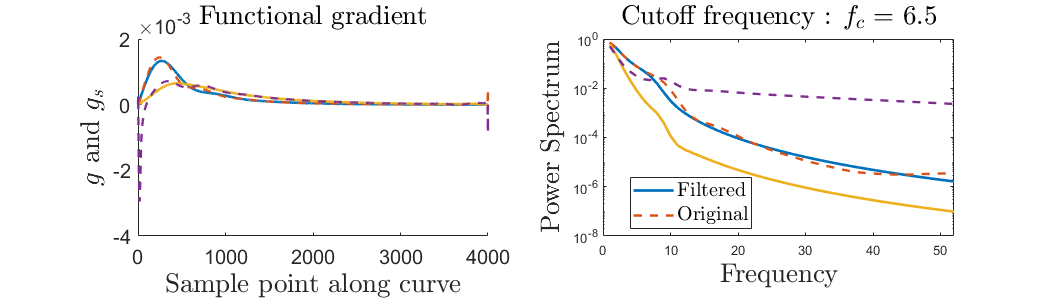

save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_PS_traj_60.png"

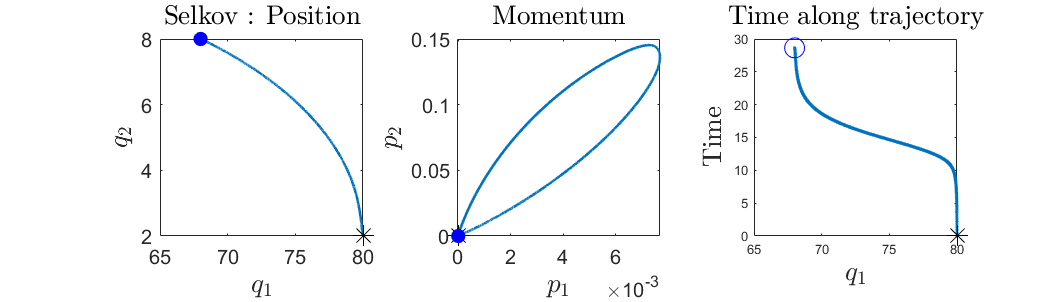

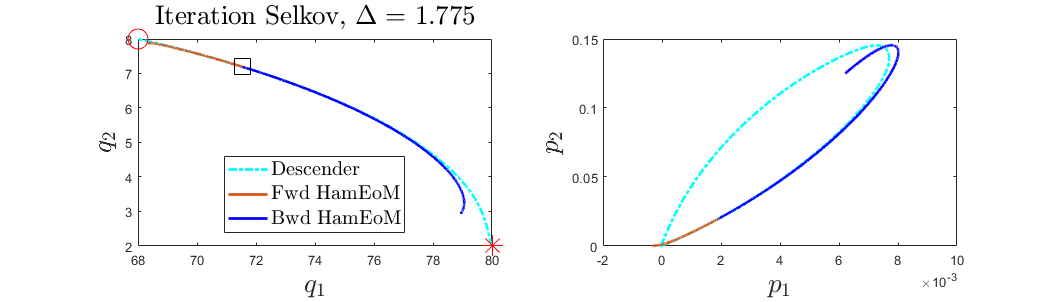

a =    1.775370721787327


delta_S =      4.775395546663397e-06


delta_S =      8.041898196198272e-06


delta_S =     -3.858344882312625e-06


ans = 1×5
  61.000000000000000   0.250000000000000   0.446417259867423  -0.000003858344882   6.499999999999992


a_min =    1.772564147785160


delta_S =      1.208466033675304e-05


delta_S =      7.167224858384280e-06


delta_S =      4.543212539898089e-06


delta_S =      9.437248724153413e-07


delta_S =      1.871113196605378e-07


delta_S =     -4.867668420838189e-06


ans = 1×5
  62.000000000000000   0.007812500000000   0.446412392199002  -0.000004867668421   6.499999999999992


a_min =    1.772476740211472


delta_S =      3.303821198508139e-06


delta_S =     -4.850305296844049e-07


ans = 1×5
  63.000000000000000   0.003906250000000   0.446411907168472  -0.000000485030530   6.499999999999992


a_min =    1.772479891127040


delta_S =      1.461077918729625e-05


delta_S =      1.381775623621184e-05


delta_S =      1.199635783749597e-05


delta_S =      1.558007907276338e-05


delta_S =      1.218097783006744e-05


delta_S =      1.278617593275522e-05


delta_S =      1.350482924528107e-05


delta_S =      1.347531407719371e-05


delta_S =      1.270224730232083e-05


ans = 1×5
  64.000000000000000                   0   0.446411907168472                   0   6.599999999999992


a_min =    1.772539412585024


delta_S =      5.951712719221014e-06


delta_S =     -2.683201355213605e-06


ans = 1×5
  65.000000000000000   0.500000000000000   0.446409223967117  -0.000002683201355   6.699999999999991


a_min =    1.766955151141983


delta_S =      3.899272283058863e-06


delta_S =     -7.349356251906691e-07


ans = 1×5
  66.000000000000000   0.250000000000000   0.446408489031492  -0.000000734935625   6.699999999999991


a_min =    1.764172505753820


delta_S =      3.933207840645103e-06


delta_S =      1.858421047695735e-05


delta_S =      1.163620217542460e-05


delta_S =      1.903412885362332e-05


delta_S =      1.359747478019147e-05


delta_S =     -6.746731653906046e-07


ans = 1×5
  67.000000000000000   0.007812500000000   0.446407814358326  -0.000000674673165   6.699999999999991


a_min =    1.764085779444120


delta_S =      1.426102782542404e-05


delta_S =      1.461528990054362e-07


ans = 1×5
  68.000000000000000                   0   0.446407814358326                   0   6.699999999999991


a_min =    1.764114150261333


delta_S =     -4.647683541136871e-06


ans = 1×5
  69.000000000000000   1.000000000000000   0.446403166674785  -0.000004647683541   6.799999999999991


a_min =    1.752989872176771


delta_S =     -6.602780620812432e-06


ans = 1×5
  70.000000000000000   1.000000000000000   0.446396563894164  -0.000006602780621   6.799999999999991


a_min =    1.741940077440810


save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_deltax_70.png"

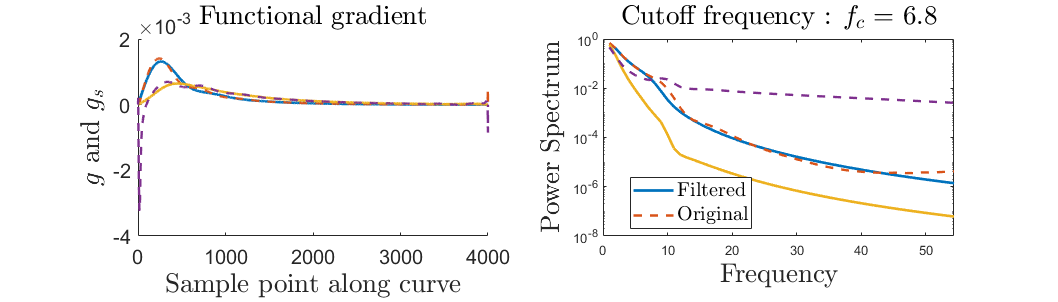

save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_PS_traj_70.png"

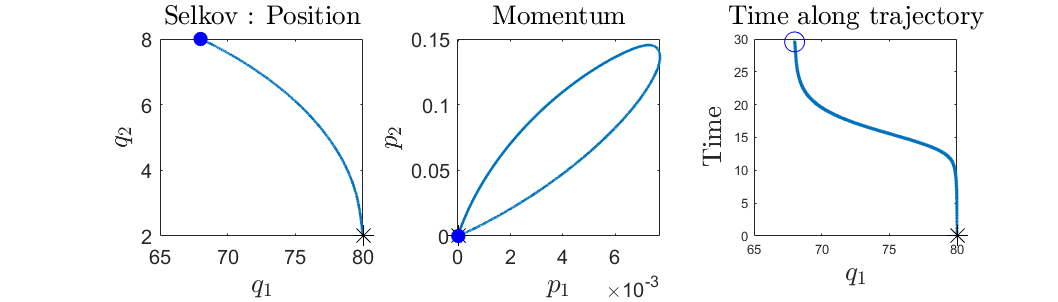

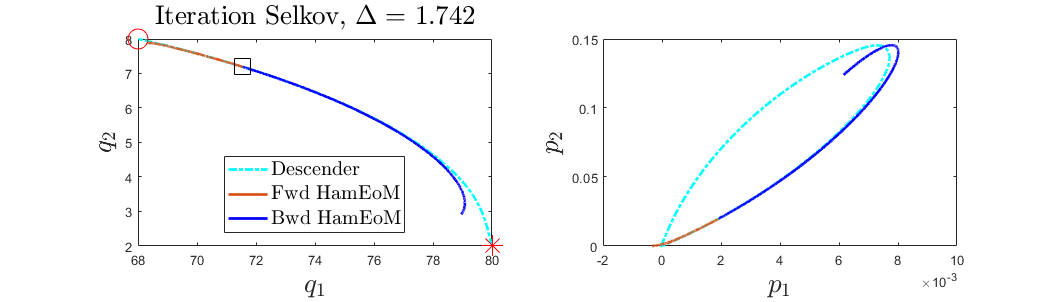

a =    1.741940077440810


delta_S =     -5.650922594857555e-06


ans = 1×5
  71.000000000000000   1.000000000000000   0.446390912971569  -0.000005650922595   6.799999999999991


a_min =    1.730976345842311


delta_S =     -4.133926870375504e-06


ans = 1×5
  72.000000000000000   1.000000000000000   0.446386779044699  -0.000004133926870   6.799999999999991


a_min =    1.720100918216255


delta_S =     -1.041429678289019e-05


ans = 1×5
  73.000000000000000   1.000000000000000   0.446376364747916  -0.000010414296783   6.799999999999991


a_min =    1.709306087140823


delta_S =      1.423163760166934e-05


delta_S =      1.931424435996920e-06


delta_S =      9.430722837211469e-06


delta_S =      2.796944388261391e-06


delta_S =      3.764798417460469e-08


ans = 1×5
  74.000000000000000                   0   0.446376364747916                   0   6.799999999999991


a_min =    1.709362977475413


delta_S =      1.384759569245109e-05


delta_S =      1.574081727384602e-05


delta_S =      1.738017775448908e-05


delta_S =      1.868464478910203e-05


delta_S =      1.860652077362301e-05


delta_S =      2.001165803178218e-05


delta_S =      1.985381934976882e-05


delta_S =      1.977710425282719e-05


delta_S =      1.991370153892058e-05


ans = 1×5
  75.000000000000000                   0   0.446376364747916                   0   6.899999999999991


a_min =    1.709389198183900


delta_S =      1.242985989124978e-05


delta_S =      1.567455396817019e-05


delta_S =      1.729949399192909e-05


delta_S =      1.940059855759513e-05


delta_S =      1.924593217766946e-05


delta_S =      1.890192217213205e-05


delta_S =      1.899063696497727e-05


delta_S =      1.920179365011432e-05


delta_S =      1.934490447441650e-05


ans = 1×5
  76.000000000000000                   0   0.446376364747916                   0   6.999999999999990


a_min =    1.709418399794388


delta_S =      1.367206828983836e-05


delta_S =      1.592258864457907e-05


delta_S =      1.664531206935216e-05


delta_S =      1.779153778547204e-05


delta_S =      1.968400162261075e-05


delta_S =      1.984389676579212e-05


delta_S =      1.984782806740970e-05


delta_S =      1.953166856516475e-05


delta_S =      1.948296081050183e-05


ans = 1×5
  77.000000000000000                   0   0.446376364747916                   0   7.099999999999990


a_min =    1.709461446980039


delta_S =      9.901265297374007e-06


delta_S =      1.567035860416954e-05


delta_S =      1.709121088727672e-05


delta_S =      1.708679617978826e-05


delta_S =      1.834137872397390e-05


delta_S =      1.653757682917867e-05


delta_S =      1.199242599020378e-05


delta_S =      1.985482939320660e-05


delta_S =      2.002738819195660e-05


ans = 1×5
  78.000000000000000                   0   0.446376364747916                   0   7.199999999999990


a_min =    1.709515578202593


delta_S =      1.317693429164768e-05


delta_S =      1.559255110922253e-05


delta_S =      1.710276911459641e-05


delta_S =      1.725545118441696e-05


delta_S =      1.757071387731290e-05


delta_S =      1.883376627398459e-05


delta_S =      1.887253077065276e-05


delta_S =      1.892632257149973e-05


delta_S =      1.906697279246972e-05


ans = 1×5
  79.000000000000000                   0   0.446376364747916                   0   7.299999999999989


a_min =    1.709547225561292


delta_S =      1.122821260024498e-05


delta_S =      1.458767616774326e-05


delta_S =      1.744718512675103e-05


delta_S =      1.782650064779956e-05


delta_S =      1.765660505748112e-05


delta_S =      1.738330106582087e-05


delta_S =      1.765874132642065e-05


delta_S =      1.797124508745584e-05


delta_S =      1.766677838821451e-05


ans = 1×5
  80.000000000000000                   0   0.446376364747916                   0   7.399999999999989


a_min =    1.709579352001821


save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_deltax_80.png"

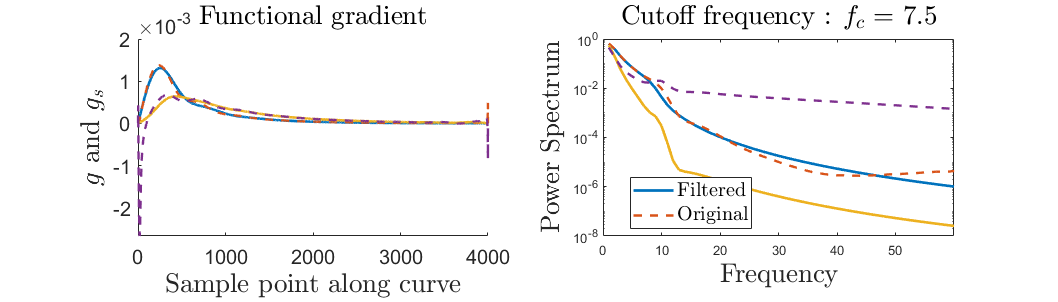

save_plot_name = "Plots/Selkov/Selkov_1_2_4000_11-Aug-2022_PS_traj_80.png"

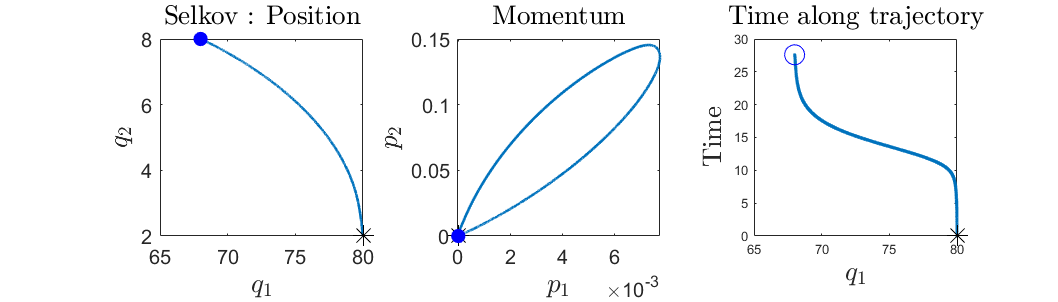

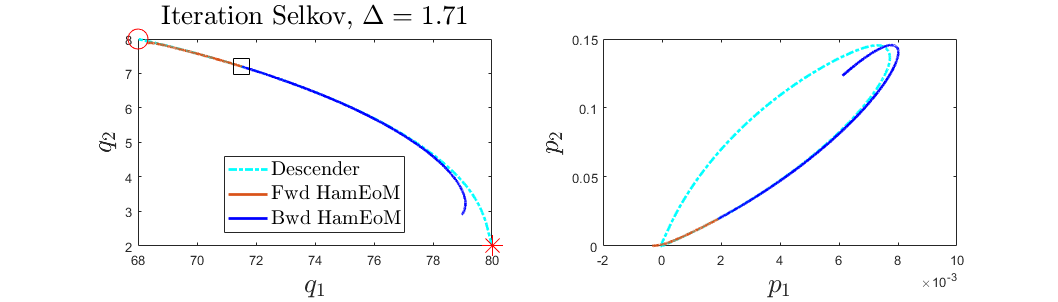

a =    1.709579352001821


format long
anneal_ct = 0;
while f0<f0_max  &&  iter<iter_max && a_min>a_thresh
    iter = iter + 1;
    traj_pts = size(traj,1);

    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh_eps);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;

    

    if abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = eps_ic; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,time_uniform_f);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    %Find closest distance by integrating HamEoM
    a_min = Ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,10)==0
        save_plot_name = save_plot_name_root +'_deltax_'+string(iter)+'.png'
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root +'_PS_traj_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root + '_HamEoM_' + string(iter)+'.png';
        a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)
    end

    
end

format short

format long
S_arr(end)

save_plot_name

        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);


#### Look for a setting which works

format long
f0 = 6; eps_min = 0.001;eps = 0.5;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

traj_pts_new = 3000;
traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
%[traj,len_curve_prime] = space_uniform_sampling(traj_n_s,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

f0 = 6; eps_min = 0.03;eps = 0.1;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

iter = 55;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
save_plot_name = save_plot_name_root + '_' + string(iter) + '_HamEoM';
a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)


debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

#### Filter trajectory and see if that reduces a_min

iter = size(S_arr,1)
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
traj = PS_traj(:,1:num_spec);
a_arr_filter = [];

figure()
plot(traj(:,1),traj(:,2))
hold on
for i = 1:12
    traj = time_uniform_filter(traj,t_traj,traj_pts,35);
    [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
    [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    a_min = Ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,0,plotnam)
    a_arr_filter = [a_arr_filter; a_min];
    traj = PS_traj(:,1:num_spec);
    plot(traj(:,1),traj(:,2))
end
     hold off

figure()
plot(a_arr_filter)



## Save a trajectory for annealing

iter = 177;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
traj = PS_traj(:,1:num_spec);
traj = time_uniform_filter(traj,t_traj,traj_pts+1500,time_uniform_f);
[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts+1500);
size(traj)
save('..\Data\Selkov_4000_anneal_traj.mat','traj')

